P.8

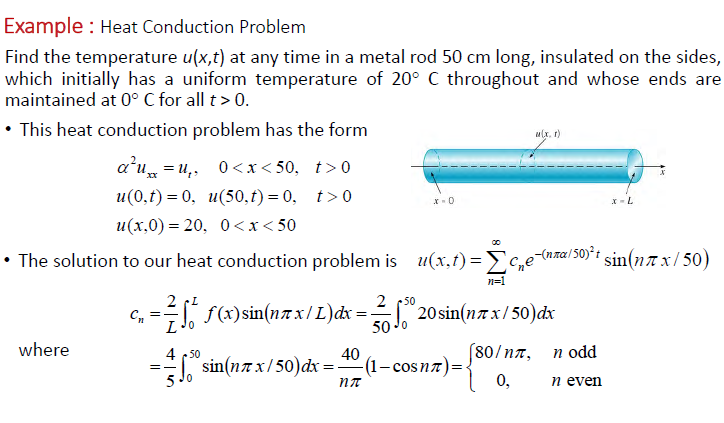

clear
clf
clc
syms x t u(x,t) L D
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0; 
BCL = u(L,t) == 0;
BCt = u(x,0) == 20;
syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)=\text{D}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)$$

BCx0 = subs(BC0,u(0,t),X(0)*T(t)/T(t))

$$BCx0 = X\left(0\right)=0$$

BCxL = subs(BCL,u(L,t),X(L)*T(t)/T(t))

$$BCxL = X\left(L\right)=0$$

BCt0 = subs(BCt,u(x,0),X(x)*T(0)/X(x))

$$BCt0 = T\left(0\right)=20$$

SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

var = children(SepVar);
syms lambda
assume(lambda,"positive") 
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT,BCt0)

$$T(t, lambda) = 20\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

sln = X(L,lambda)

$$sln = C_{2}\,\sin\left(L\,\lambda \right)$$

[lambda,parameters,conditions] = solve(sln == 0,lambda,"ReturnConditions",true)

$$lambda = \frac{\pi \,k}{L}$$

$$parameters = k$$

$$conditions = k\in \mathbb{Z}\wedge C_{2}\neq 0\wedge 1\leq k$$

n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{L}$$

syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin" "exp"])

$$ustruct(x, t, n) = \left(20\,b_{n}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

syms x m n L
assume([m,n],["integer","positive"]); assume(L,"positive");
lambda(n) = n*pi/L;
e(n) = sin(lambda(n)*x)

$$e(n) = \sin\left(\frac{\pi \,n\,x}{L}\right)$$

assume(n,"integer")
L = 50;
phi(x) = piecewise(x<L/2,x,x>L/2,L/2);
D = 1;
N = 500;
c_n= simplify(2/L*int(sin(n*x*pi/L),0,L))

$$c\_n = -\frac{2\,\left({\left(-1\right)}^{n}-1\right)}{n\,\pi }$$

buildHeatStruct = subs(ustruct(x,t,n),sym('b_n'),c_n);
heatStruct = buildHeatStruct;
heatStructEmb(x,t,n) = subs(heatStruct,sym(["c_n" "L" "D"]),[c_n L D])

$$heatStructEmb(x, t, n) = -\frac{40\,\sin\left(\frac{\pi \,n\,x}{50}\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{2500}}\,\left({\left(-1\right)}^{n}-1\right)}{n\,\pi }$$

heatSolN(x,t) = simplify(symsum(heatStructEmb,n,1,N))

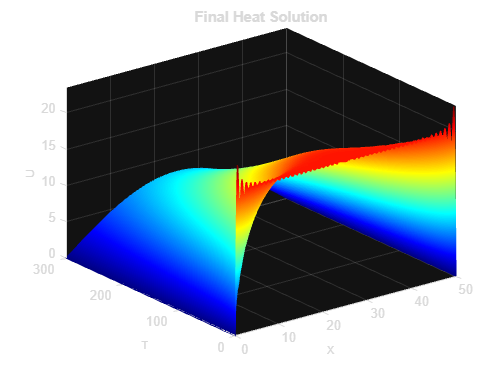

figure
colormap jet
tau = L^2/D;
fsurf(heatSolN,[0 L 0 tau/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('X','FontSize',8);
ylabel('T','FontSize',8); 
ylim([0 300]);
zlabel('U','FontSize',8);

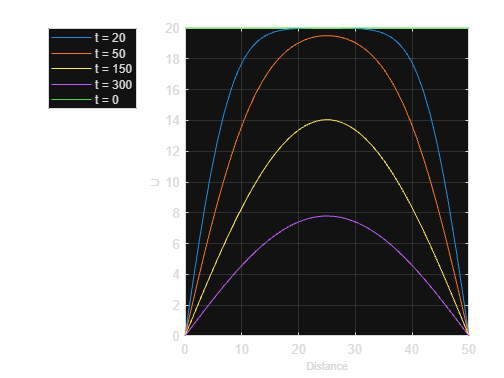


clf
tm = [20 50 150 300];
for i = 1:length(tm)
    sn = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn, [0 L])
    grid on, hold on
end 
sn = 20;
fplot(sn, [0 L])
xlabel('Distance','FontSize',8);
ylabel('U','Fontsize',8)
legend('t = 20' , 't = 50' , 't = 150' , 't = 300' , 't = 0' , 'Location','northwestoutside')

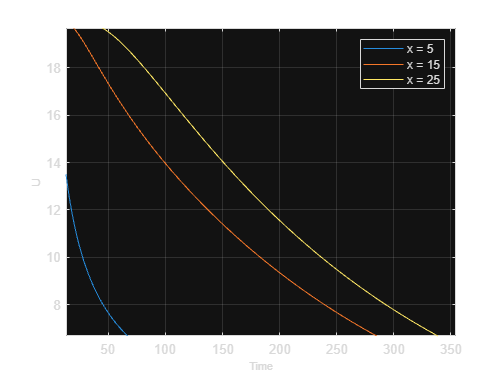

clf
dst = [5 15 25];
for i = 1:length(dst)
    sn = matlabFunction(heatSolN(dst(i),t));
    fplot(sn, [0 500])
    grid on, hold on
end 
xlabel('Time','FontSize',8);
ylabel('U','Fontsize',8)
legend('x = 5' , 'x = 15' , 'x = 25'  , 'Location','northeast')